# Robo Week 6

## Visualization

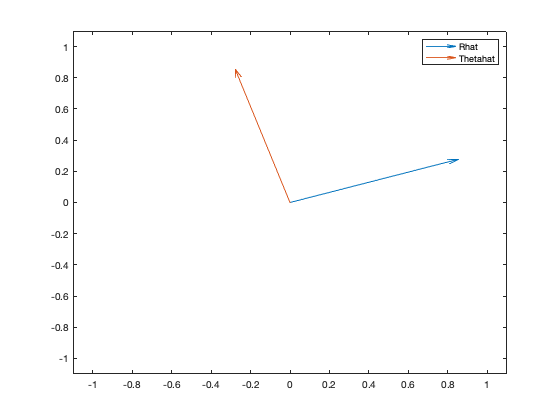

clf;
theta = 0.1 * pi;
rhat = [cos(theta), sin(theta)];
thetahat = [-sin(theta), cos(theta)];
quiver(0, 0, rhat(1), rhat(2));hold on;
quiver(0, 0, thetahat(1), thetahat(2));
legend("Rhat", "Thetahat");
xlim([-1.1, 1.1]);
ylim([-1.1, 1.1]);

## Exercise 26.1 & 26.2

cart2pol(-8, 6) % 26.1.1

ans = 2.4981

cart2pol(5, 12) % 26.1.2

ans = 1.1760

pol2cart(2, pi / 6) % 26.2.1

ans = -0.2179

pol2cart(2, -pi / 3) % 26.2.2

ans = 0.4358

## Exercise 26.5

load("scan1")
who -file scan1


Your variables are:

r      theta  



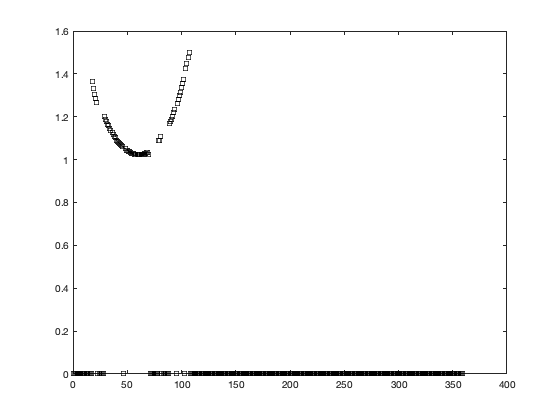

clf; plot(theta, r, 'ks'); % 26.5.1

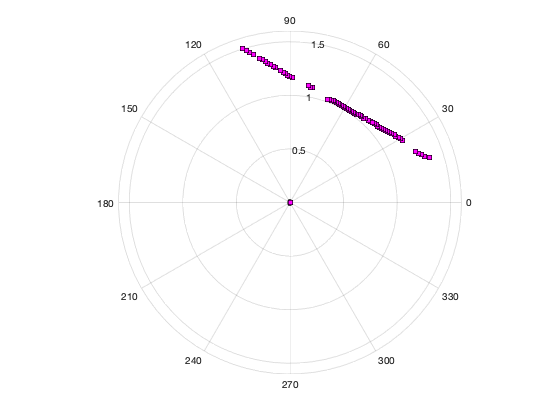

figure; clf; polarplot(deg2rad(theta), r, 'ks', 'MarkerSize', 6, 'MarkerFaceColor', 'm'); % 26.5.2

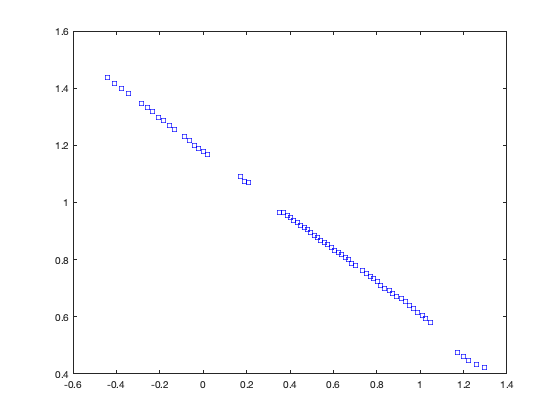

% 25.6.4
mask = r ~= 0;
r_clean = r(mask);
theta_clean = theta(mask);
[x, y] = pol2cart(deg2rad(theta_clean), r_clean);

figure; clf; plot(x, y, 'bs'); % 25.6.5

## Exercise 26.8

clf;
load("scan2.mat")
whos -file scan2.mat

  Name         Size            Bytes  Class     Attributes

  r          360x1              1440  single              
  theta      360x1              1440  single              




[X, Y] = pol2cart(theta, r);

lobf = [X, ones(length(X), 1)] \ Y

lobf = 2×1 single column vector
    0.0882
   -0.0036



A = (1 / sqrt(length(X) - 1)) * [X - mean(X), Y - mean(Y)]

A = 360×2 single matrix
    0.1860    0.0001
    0.0997    0.1561
   -0.0792    0.1722
   -0.1870    0.0267
   -0.1241   -0.1430
   -0.0005    0.0001
    0.1802   -0.0524
   -0.0005    0.0001
   -0.0005    0.0001
   -0.0005    0.0001


R = cov(A)

R = 2×2 single matrix
	1.0e+-3 *

    0.6551    0.0578
    0.0578    0.4242


V = pca(R)

V = 2×1 single column vector
    0.8524
   -0.5229


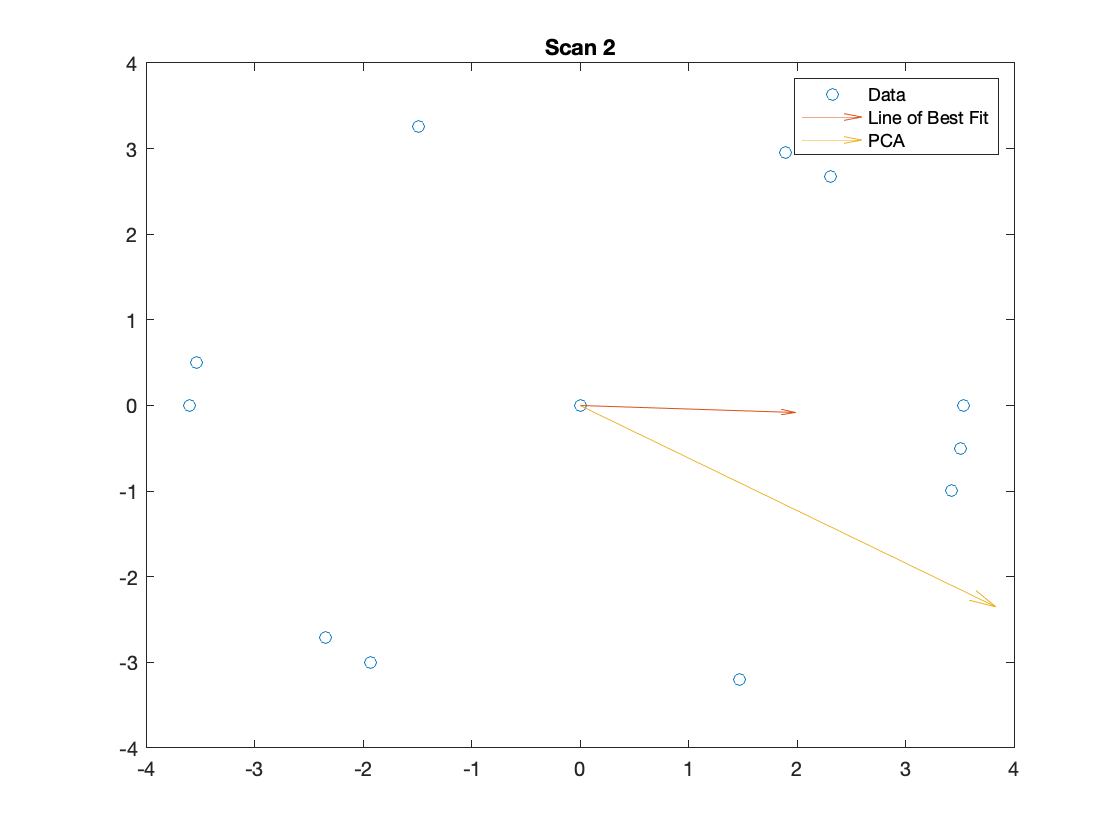


% Scale things
lobf = lobf * 25;
V = V * 5;

plot(X, Y, 'o'); hold on;
quiver(0,0, lobf(1), lobf(2));
quiver(0, 0, V(1), V(2));
legend('Data', 'Line of Best Fit', 'PCA');
title("Scan 2");


figure;

clf;
% This is broken in some unclear way that isn't important
load("scan3.mat")
whos -file scan3.mat

  Name         Size            Bytes  Class     Attributes

  r          360x1              1440  single              
  theta      360x1              1440  single              



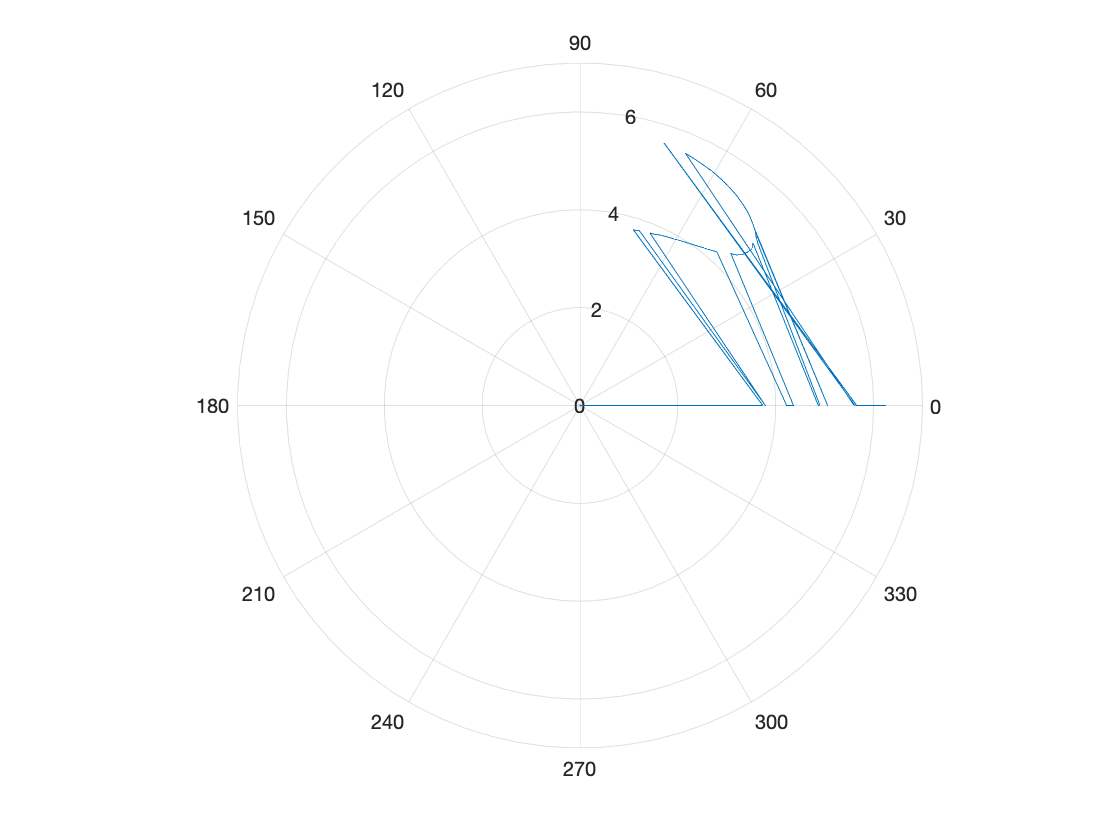

theta = deg2rad(theta);
polarplot(r, theta);

figure;

[X, Y] = pol2cart(theta, r);

lobf = [X, ones(length(X), 1)] \ Y

lobf = 2×1 single column vector
   -0.0031
   -0.1913



A = (1 / sqrt(length(X) - 1)) * [X - mean(X), Y - mean(Y)]

A = 360×2 single matrix
    0.0000    0.0101
    0.0000    0.0101
    0.0000    0.0101
    0.0000    0.0101
    0.0000    0.0101
    0.0000    0.0101
    0.0000    0.0101
    0.0000    0.0101
    0.0000    0.0101
    0.0000    0.0101


R = cov(A)

R = 2×2 single matrix
	1.0e+-3 *

    0.1911   -0.0006
   -0.0006    0.2935


V = pca(R)

V = 2×1 single column vector
   -0.5461
    0.8377


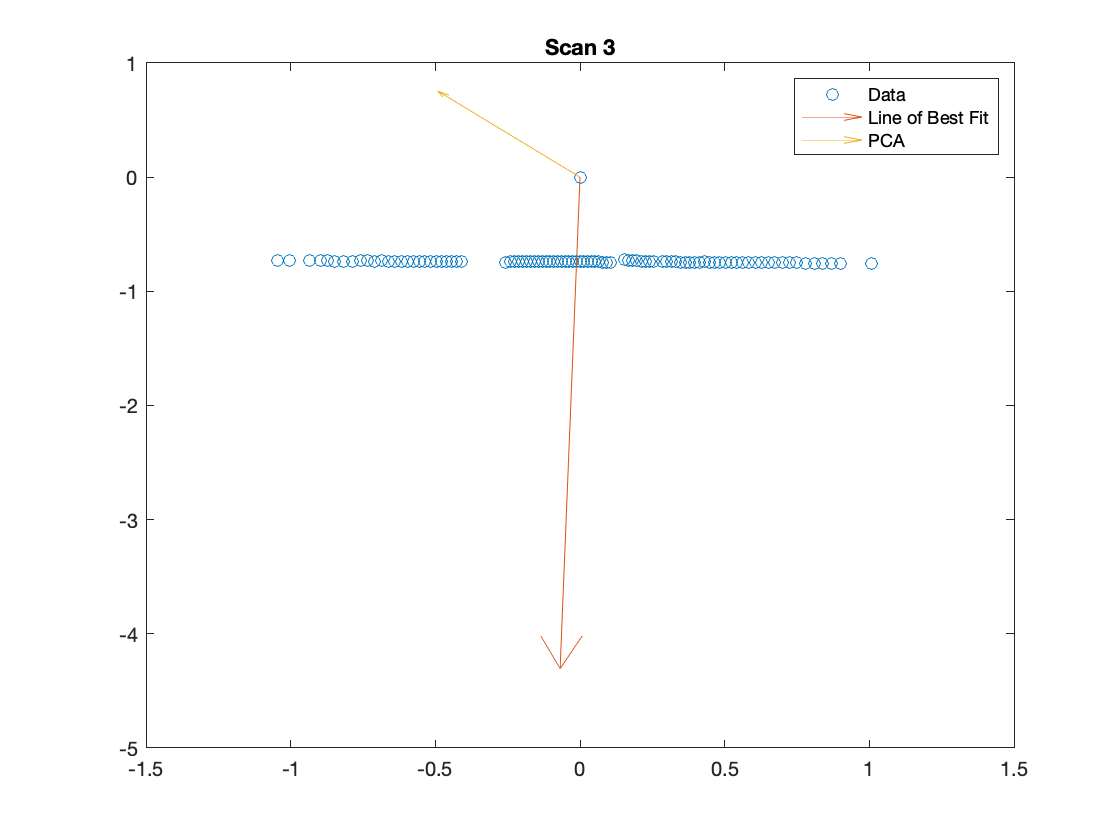


% Scale things
lobf = lobf * 25;

plot(X, Y, 'o'); hold on;
quiver(0,0, lobf(1), lobf(2));
quiver(0, 0, V(1), V(2));
legend('Data', 'Line of Best Fit', 'PCA');
title("Scan 3");